# Detecção de Outliers

Neste exercício, você vai implementar um algoritmo de detecção de anomalias e aplicá-lo para detectar falhas em servidores em uma rede.

Você deve usar um modelo baseado na Gaussiana Multivariada para detectar observações anômalos. O exercício é dividido em duas partes. Na primeira parte você vai ajustar a distribuição Gaussiana Multivariada para um dataset com duas características (bidimensional), o que permite visualizar os dados e os resultados, para então encontrar valores com baixa probabilidade que serão classificados como anomalias. Na segunda parte, você vai aplicar o algoritmo de detecção de anomalia para um dataset com maior número de dimensões.

# Parte 1

Na primeira parte vamos utilizar o arquivo DadosTreinamento1.csv que contém os dados de throughput (mb/s) e a latência (ms) das transações nos servidores. Nesse arquivo foram coletados $m=307$ observações do comportamento dos servidores representados por $\left\lbrace X_1 ,X_2 ,\cdots ,X_m \right\rbrace$. A grande maioria dessas observações correspondem a comportamento normal dos servidores (não anômalo), mas eles podem incluir algumas anomalias (outliers). Também vamos utlizar o arquivo DadosValiacao1.csv, para encontrar o limiar de decisão (epsilon) do algoritmo.

#### Passo 1: Carregar arquivos e visualizar dados de treinamento

Na parte 1 vamos usa dois arquivos, o primero com dados de treinamento e o segundo com dados de validação. Os dados de treinamento consistem de 307 observaçoes de latência e throughput do servidor, as duas características (features) que serão usadas no treinamento não supervisionado, e serão carregados na matriz Xtre, com os dados de latência na coluna 1 e de throughput na coluna 2. Os dados de validação consistem consistem de 307 observações rotuladas.

Assume-se que os dados possuem distribuição normal.

%% ======================= Carregar os arquivos  =============================
%  Carregar os arquivos da parte 1 com observações de treinamento e teste 
%  com medidas de latencia e throughput
%% ===========================================================================
clear all;

%  Carregar o conteúdo arquivos nas variáveis Xtre, Xval, Yval
Xtre = readmatrix('DadosTreinamento1.csv');
XYval = readmatrix('DadosValidacao1.csv');
Xval = XYval(:, [1,2]);
Yval = XYval(:, [3]);


#### Passo 2: Visualizar dados de treinamento

- Plotar os histogramas dos valores das características.

- Plotar o diagrama de dispersão.

fprintf('Visualização do Dataset de treinamento.\n\n');

% Histograma dos dados de treinamento
histogram(Xtre(:, 1));
histogram(Xtre(:, 2));

%  Gráfico de dispersão dos dados de treinamento
plot(Xtre(:, 1), Xtre(:, 2), 'bx');
axis([0 30 0 30]);
xlabel('Latência (ms)');
ylabel('Throughput (mb/s)');
title('Dispersão dos dados de treinamento')

#### Passo 3: Treinamento

Calcular parâmetros da distribuição Gaussiana.

A função estimarGaussiana é chamada para calcular o vetor de médias (MU) e a matriz de covariancia (SIGMA) dos dados contidos na matriz de treinamento (Xtre). 

%% ===========  Passo 3 - Treinar o modelo ==========================%%
% Para treinar o modelo devemos estimar o vetor MU e a matriz SIGMA
% Você deve alterar o código contido no arquivo estimarGaussiana.m
% de modo a estimar os parâmetros do modelo (MU e SIGMA)
[MU, SIGMA] = estimarGaussianaResposta(Xtre);

#### Passo 4: Verificar aderência do modelo

Visualizar as curvas de nível da distribuição normal multivariada em comparação com gráfico de dispersão da latência e throughput (primeira e sugunga coluna de Xtre).

Para visualizar as curvas de nível vamos chamar a função visualizarAderencia.m. Não é necessária nenhuma modificação na função.

% A função visualizar aderência plota as curvas de contorno da função
% Gaussiana Multivariada que treinamos.
visualizarAderencia(Xtre, MU, SIGMA);

#### Passo 5: Ajustar o modelo

Para ajustar o modelo vamos utiliar os dados de validação. A matriz Xval tem os dados para validação de latência e throughput (colunas 1 e 2) e o vetor Yval tem os valores rotulados correspondentes, ou seja, é um vetor de 0s e 1s sendo que 1 significa dados com anomaila e 0 dados sem anomalia.

Na fase de validação vamos calcular o valor de epsilon que define os limiar das anomalis no modelo. Os valores de Xval são passados como argumendo para a funçã oGaussina multivariada que acabamos de treinar usado os dados em Xtrei, ou seja, a Gaussiana com parâmetros Mu e SIGMA. São considerados anomalias os dados em Xval cujos valores devolvidos pela função sejam menor que um limiar episilon. Vamos usar os dados de validação (Xval e Yval) para calcular epsilon.

Primeiro chamamos a função mvnpdf para calcular os valores previstos pelo modelo (pval). Depois chamamos a função selecionarLimiar para encontrar o valor de epsilon.

A função selecionarLimiar recebe como argumento o vetor Pval que calculamos e o vetor Yval. O vetor Yval contém os rótulos das medias de latência e throughput contidas em Xval. É um vetor com 0s e 1s, com 0 significando que a latência e o trhoughpu são normais e 1 significando valores anômalos.

Você deve completar o algoritmo em selecionarLimiar. A explicação detalhada do algoritmo está no arquivo selecionarLimiar.m, que também contém a estrutura do código.

%% ================== Passo 4: Ajustar o modelo ===================
%  Encontrar um bom valor para o threshold epsilon usando as probabilidades
%  dadas pela distribuição Gaussiana estimada quando aplicada em um  
%  conjunto cross-validation
% 

Pval = mvnpdf(Xval, MU, SIGMA);

[epsilon, F1] = selecionarLimiarResposta(Yval, Pval);
fprintf('Valor de epsilon encontrado: %e\n', epsilon);
fprintf('Valor de F1 obtido usando:  %f\n', F1);
fprintf('Oo valor de epsilon deve ser 9.036141e-05\n\n');


#### Passo 6: Visualizar as anomalias no conjunto de treinamento

Se o algoritmo estiver correto você deve ver a seguinte figura:

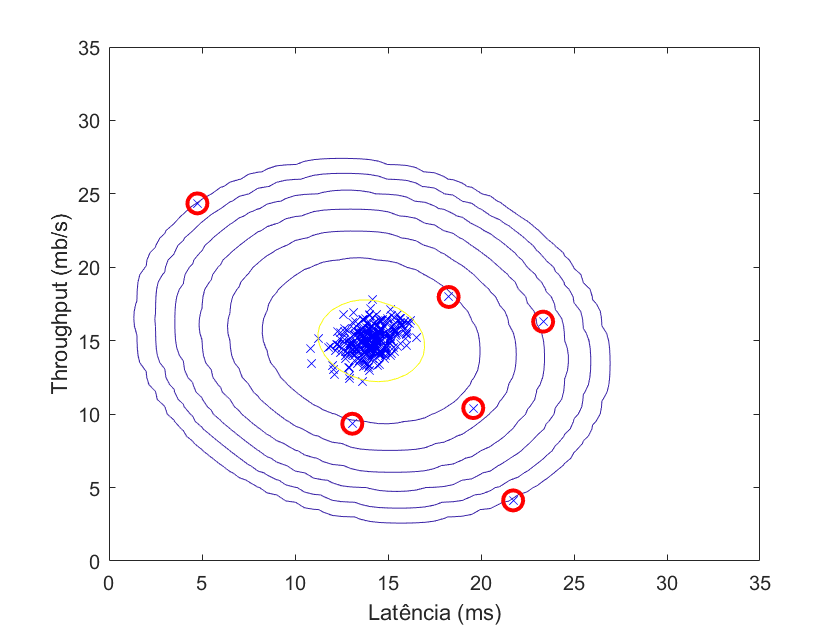

%  Encontrar as anomalias no conjunto de treinamento e mostrar no gráfico
p = mvnpdf(Xtre, MU, SIGMA);
anomalias = find(p < epsilon);


%  Desenhar um círculo vermelho em trono dos outliers
hold on
plot(Xtre(anomalias, 1), Xtre(anomalias, 2), 'ro', 'LineWidth', 2, 'MarkerSize', 10);
hold off

# Parte 2

Na primeira parte vamos utilizar os arquivos DadosTreinamento2.csv, DadosValidacao2.csv e DadosTeste2.csv, que contêm os dados de treinamento e validação e teste. Os arquivos com dados de validação e teste tambem incluem dados rotulados (Y) para uso em validação e teste.

Para esse exercício foram coletadas 11 características de desempenho dos servidores. Não é possível fazer as vizualizações anteriores, mas os algoritmo que foram implementados na pare 1 podem ser usados aqui, porque o tratamento é válido para matrizes dde dados de quaisuqer dimensão.

#### Ler dos arquivos de treinamento e validação

clear all;
%  Carregar o conteúdo arquivos nas variáveis Xtre, Xval, Yval
Xtre = readmatrix('DadosTreinamento2.csv');
XYval = readmatrix('DadosValidacao2.csv');
Xval = XYval(:, 1:11);
Yval = XYval(:, [12]);


#### Treinar o modelo

% Calcular MU e SIGMA
[MU, SIGMA] = estimarGaussianaResposta(Xtre);

#### Ajustar o modelo

%  Encontrar um bom valor para o limiar epsilon 
% 
Pval = mvnpdf(Xval, MU, SIGMA);
[epsilon, F1] = selecionarLimiarResposta(Yval, Pval);

fprintf('Valor de epsilon encontrado: %e\n', epsilon);
fprintf('Valor de F1 obtido usando:  %f\n', F1);
fprintf('O valor de epsilon deve ser 1.824432e-18\n\n');

#### Testar o modelo

Para testar o modelo vamos carrgar o arquivo DadosTeste2.csv que contém os valores de teste, incluindo os dados rotulados. Vamos calcular a métrica F1 para os dados de teste.

Copiar os valores de acuracidade, e das métricas prec, rec e F1 para o arquivo Problemas em Equipe 6.doc.

XYtest = readmatrix('DadosTeste2.csv');
Xtest = XYtest(:, 1:11);
Ytest = XYtest(:, [12]);

p = mvnpdf(Xtest, MU, SIGMA);
anomalias = (p < epsilon);

vp = sum((anomalias==1) & (Ytest==1));
vn = sum((anomalias==0) & (Ytest==0));
fp = sum((anomalias==1) & (Ytest==0));
fn = sum((anomalias==0) & (Ytest==1));
acuracidade = (vp+vn)/size(Ytest, 1)
prec = vp/(vp+fp)
rec = vp/(vp+fn)
F1 = (2*prec*rec) / (prec+rec)